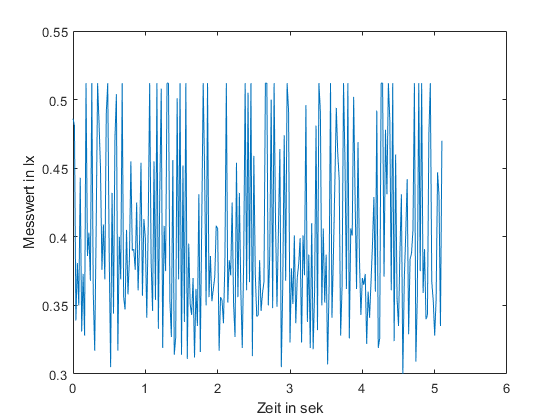

fid_deg_256_100 = fopen('daten_256_100_deg.txt');
fid_deg_256_20 = fopen('daten_256_20_deg.txt');
fid_deg_128_40 = fopen('daten_128_40_deg.txt');

fid_lx_256_100 = fopen('daten_256_100_lx.txt');
fid_lx_256_20 = fopen('daten_256_20_lx.txt');
fid_lx_128_40 = fopen('daten_128_40_lx.txt');


fid = fid_lx_256_20;


x_vector = [];
y_vector = [];

while ~feof(fid)
    cur_cell = strsplit(fgetl(fid));
    x_vector = [x_vector cur_cell(1)];
    y_vector = [y_vector cur_cell(2)];
    
end

x_vector = str2double(x_vector);
y_vector = str2double(y_vector);


plot(x_vector, y_vector)

xlabel('Zeit in sek')
ylabel('Messwert in lx')